y'''' + 4y'' + 4y = 0, y(0) = 1

, y'(0) = 0, y''(0) = 0, y'''(0) = -4

% Define the ODE and initial conditions
f = @(t, y) [y(2); y(3); y(4); -4*y(3) - 4*y(1)];
y0 = [1; 0; 0; -4];

% Define the exact solution
exact_sol = @(x) ((x - 1) .* sin(sqrt(2) .* x))/sqrt(2) + (x + 1) .* cos(sqrt(2) .* x);

% Define the time interval and step size
t0 = 0;
tf = 10000;
h = 0.1;
tspan = t0:h:tf;


% Compute the approximate solution using the Adams-Bashforth method
tic
[t_AB, y_AB] = adams_bashforth(f, y0, tspan, h);
time_AB = toc* 1000;

% Compute the approximate solution using the Adams-Moulton method
tic
[t_AM, y_AM] = adams_moulton(f, y0, tspan, h);
time_AM = toc* 1000;

% Compute the exact solution
y_exact = exact_sol(tspan)

y_exact = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001   -0.0000    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006



y_AB_t = y_AB(:,1).'

y_AB_t =     1.0000    1.0000    1.0000    0.9923    0.9694    0.9293    0.8676    0.7803    0.6645    0.5180    0.3396    0.1292   -0.1122   -0.3824   -0.6780   -0.9944   -1.3259   -1.6659   -2.0069   -2.3405   -2.6581   -2.9506   -3.2089   -3.4241   -3.5878   -3.6921   -3.7303   -3.6967   -3.5870   -3.3985   -3.1303   -2.7832   -2.3599   -1.8651   -1.3055   -0.6895   -0.0273    0.6694    1.3874    2.1125    2.8296    3.5231    4.1772    4.7764    5.3054    5.7501    6.0976    6.3366    6.4575    6.4532


y_AM_t = y_AM(:,1).'

y_AM_t = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001   -0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007



% Calculate the errors
error_ab = abs(y_AB_t - y_exact);
error_am = abs(y_AM_t - y_exact);

% Error per
per_error_arr_ab = abs(error_ab ./ y_exact * 100)

per_error_arr_ab = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0003    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0028    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


per_error_arr_am = abs(error_am ./ y_exact * 100)

per_error_arr_am = 1.0e+07 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



% Mean Error Per
mean_error_ab = mean(per_error_arr_ab(2:end))

mean_error_ab = 98.3978

mean_error_am = mean(per_error_arr_am(2:end))

mean_error_am = 1.6086e+03

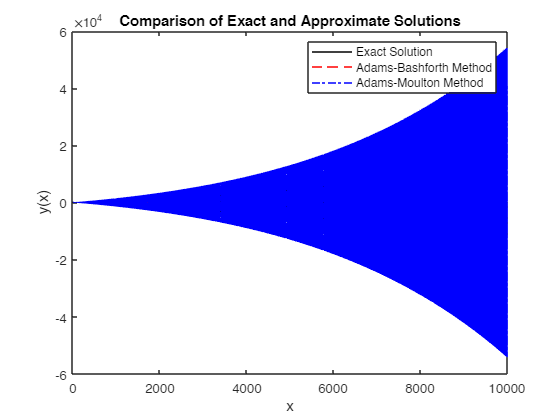


% Plot the results
figure;
plot(tspan, y_exact, 'k-', t_AB, y_AB(:,1), 'r--', t_AM, y_AM(:,1), 'b-.');
xlabel('x');
ylabel('y(x)');
title('Comparison of Exact and Approximate Solutions');
legend('Exact Solution', 'Adams-Bashforth Method', 'Adams-Moulton Method');


% Print the time taken for each method
fprintf('Time taken for Adams-Bashforth method: %f milliseconds\n', time_AB);

Time taken for Adams-Bashforth method: 209.448000 milliseconds


fprintf('Time taken for Adams-Moulton method: %f milliseconds\n', time_AM);

Time taken for Adams-Moulton method: 330.496400 milliseconds


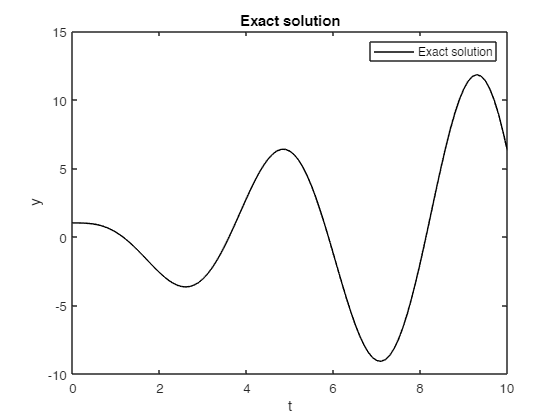

figure;
plot(tspan, y_exact, 'black-');
xlabel('t');
ylabel('y');
legend('Exact solution');
title('Exact solution');

function [t, y] = adams_bashforth(f, y0, tspan, h)
% Solve an ODE using the Adams-Bashforth method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Bashforth method to compute the remaining values of y
for i = 3:length(t)-1
    y(i+1,:) = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
end
end


function [t, y] = adams_moulton(f, y0, tspan, h)
% Solve an ODE using the Adams-Moulton method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Moulton method to compute the remaining values of y
for i = 3:length(t)-1
    % Adams-Bashforth Order 3 (yn+3)
    y_predictor = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
    % Corrector using Adams-Moulton method of order 3 (yn+2)
    y_corrector = y(i,:) + (h/12)*(5*f(t(i+1), y_predictor) + 8*f(t(i), y(i,:)) - f(t(i-1), y(i-1,:)))';
    y(i+1,:) = y_corrector;
end

end